clear;
load("basicTaskDetectorHiddenIgnore.mat");

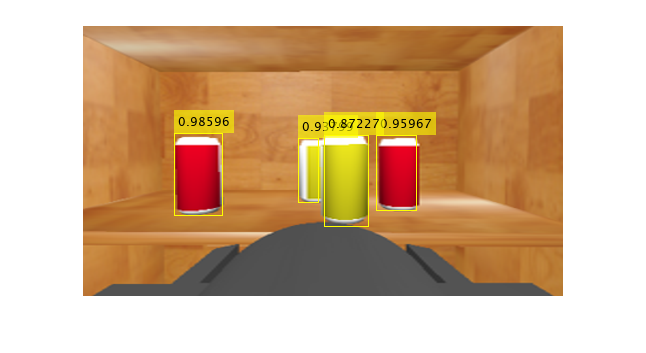

% Test on images that have hidden objects
img = imread("ImageSetHidden\hide2.png");
% img = imread("ImageSet2\shot04.png");
img = imresize(img, [224, 224]);

[bboxes, scores] = detect(detector, img);

% Resize the output bbox and image to original size.
resized_bbox = bboxes;
inputSize = [224, 224];
original_size = [270, 480];
resized_bbox(:, 1) = bboxes(:, 1) * original_size(1, 2) / inputSize(1, 2);
resized_bbox(:, 2) = bboxes(:, 2) * original_size(1, 1) / inputSize(1, 1);
resized_bbox(:, 3) = bboxes(:, 3) * original_size(1, 2) / inputSize(1, 2);
resized_bbox(:, 4) = bboxes(:, 4) * original_size(1, 1) / inputSize(1, 1);

img = imresize(img, original_size);

if(~isempty(bboxes))
    img = insertObjectAnnotation(img,'rectangle',resized_bbox,scores);
end
figure
imshow(img)

% Load dataset
load("PickPlaceYOLOHiddenIgnore\basicTaskHiddenIgnore_T.mat");  % Change the directory if needed
canDataset = data_struct.canTrainingData;

% Random shuffle all images
rng(0);
shuffledIndices = randperm(height(canDataset));
idx = floor(0.8 * length(shuffledIndices));

% Split train, validation and test data: 0.8, 0.1, 0.1
trainingIdx = 1:idx;
validationIdx = idx + 1: idx + 1 + floor(0.1 * length(shuffledIndices));
testIdx = validationIdx(end) + 1: length(shuffledIndices);

trainingDataTbl = canDataset(shuffledIndices(trainingIdx), :);
validationDataTbl = canDataset(shuffledIndices(validationIdx), :);
testDataTbl = canDataset(shuffledIndices(testIdx), :);

imdsTrain = imageDatastore(trainingDataTbl.imageFilename);
bldsTrain = boxLabelDatastore(trainingDataTbl(:,2:end));
imdsValidation = imageDatastore(validationDataTbl.imageFilename);
bldsValidation = boxLabelDatastore(validationDataTbl(:, 2:end));
imdsTest = imageDatastore(testDataTbl.imageFilename);
bldsTest = boxLabelDatastore(testDataTbl(:, 2:end));

trainDataStore= combine(imdsTrain, bldsTrain);
validationDataStore = combine(imdsValidation, bldsValidation);
testDataStore = combine(imdsTest, bldsTest);

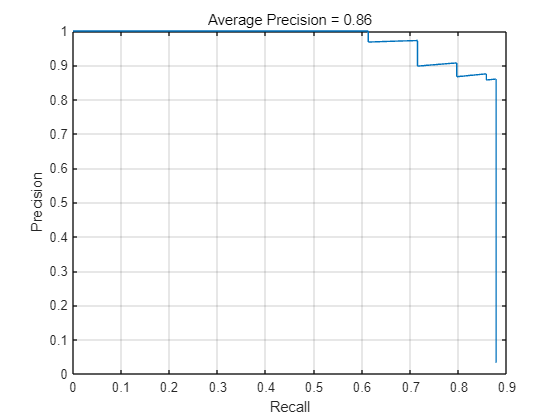

% Examine on test set
preprocessedTestData = transform(testDataStore,@(data)preprocessData(data,inputSize));

detectionThreshold = 0.01;
detectionResults = detect(detector, preprocessedTestData, Threshold=detectionThreshold);

metrics = evaluateObjectDetection(detectionResults,preprocessedTestData);

classID = 'yellow';
precision = metrics.ClassMetrics.Precision{classID};
recall = metrics.ClassMetrics.Recall{classID};

figure
plot(recall,precision)
xlabel("Recall")
ylabel("Precision")
grid on
title(sprintf("Average Precision = %.2f",metrics.ClassMetrics.mAP(classID)))

### Helper functions used in this script

function B = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.

B = cell(size(A));

I = A{1};
sz = size(I);
if numel(sz)==3 && sz(3) == 3
    I = jitterColorHSV(I,...
        'Contrast',0.2,...
        'Hue',0,...
        'Saturation',0.1,...
        'Brightness',0.2);
end

% Randomly flip and scale image.
tform = randomAffine2d('XReflection',true,'Scale',[1 1.1]);
rout = affineOutputView(sz,tform,'BoundsStyle','CenterOutput');
B{1} = imwarp(I,tform,'OutputView',rout);

% Sanitize boxes, if needed. This helper function is attached as a
% supporting file. Open the example in MATLAB to access this function.
A{2} = helperSanitizeBoxes(A{2});

% Apply same transform to boxes.
[B{2},indices] = bboxwarp(A{2},tform,rout,'OverlapThreshold',0.25);
B{3} = A{3}(indices);

% Return original data only when all boxes are removed by warping.
if isempty(indices)
    B = A;
end
end

function data = preprocessData(data,targetSize)
% Resize image and bounding boxes to the targetSize.
sz = size(data{1},[1 2]);
scale = targetSize(1:2)./sz;
data{1} = imresize(data{1},targetSize(1:2));

% Sanitize boxes, if needed. This helper function is attached as a
% supporting file. Open the example in MATLAB to access this function.
data{2} = helperSanitizeBoxes(data{2});

% Resize boxes to new image size.
data{2} = bboxresize(data{2},scale);
end